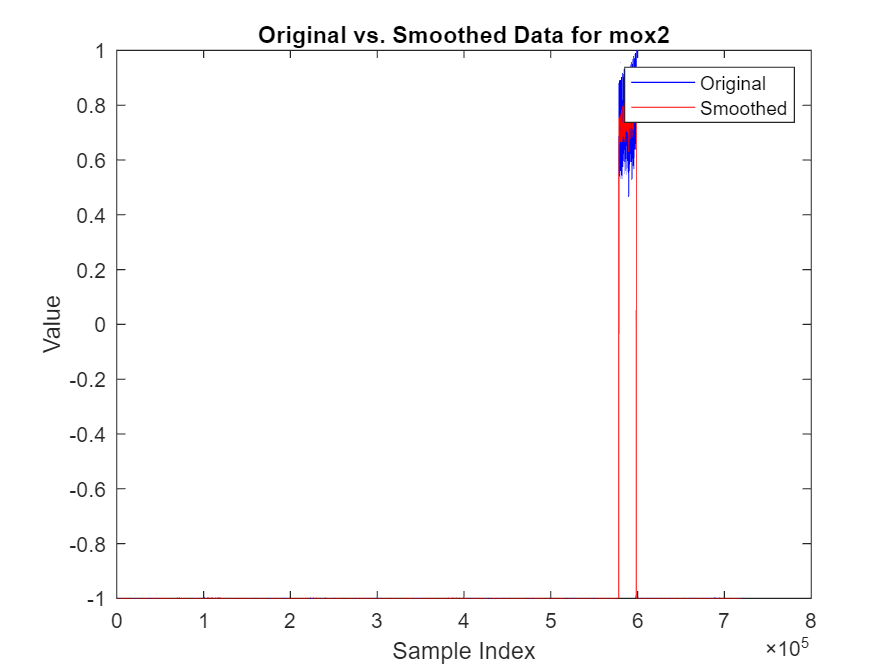

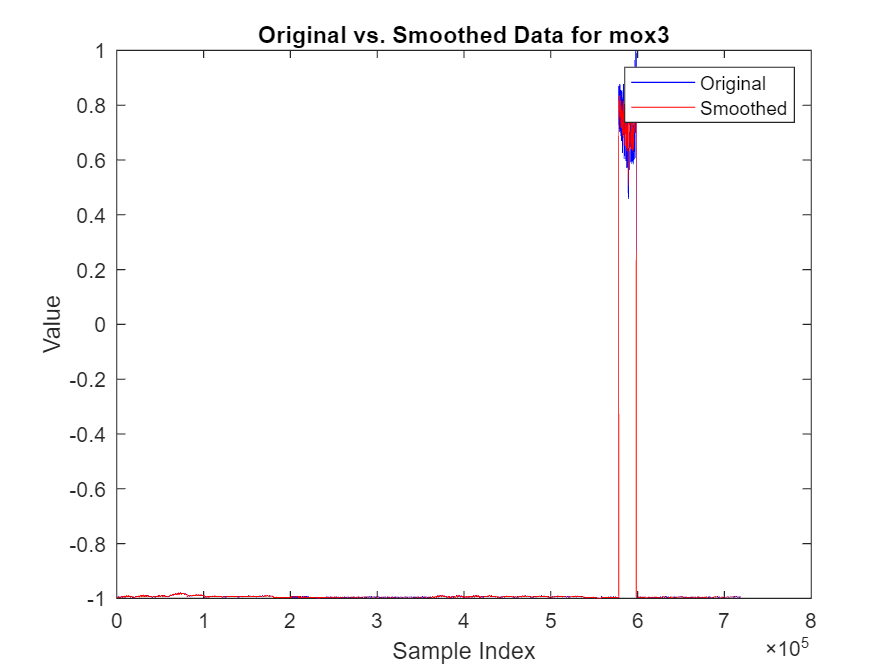

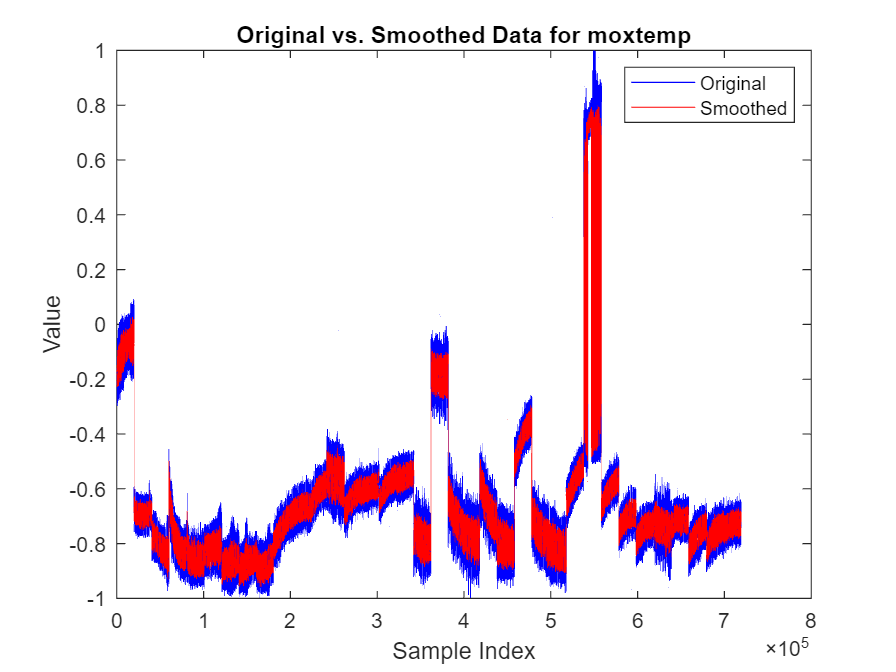

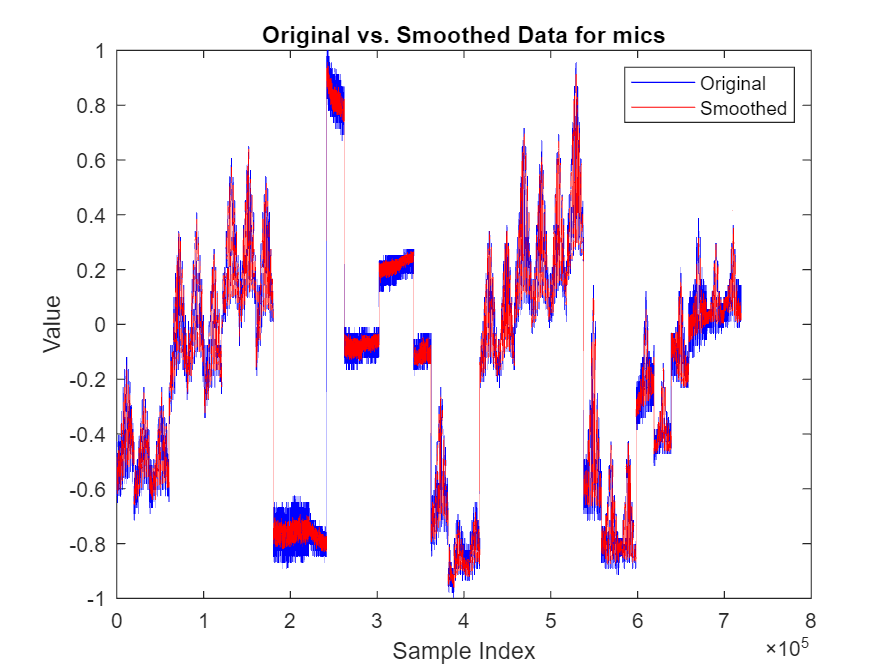

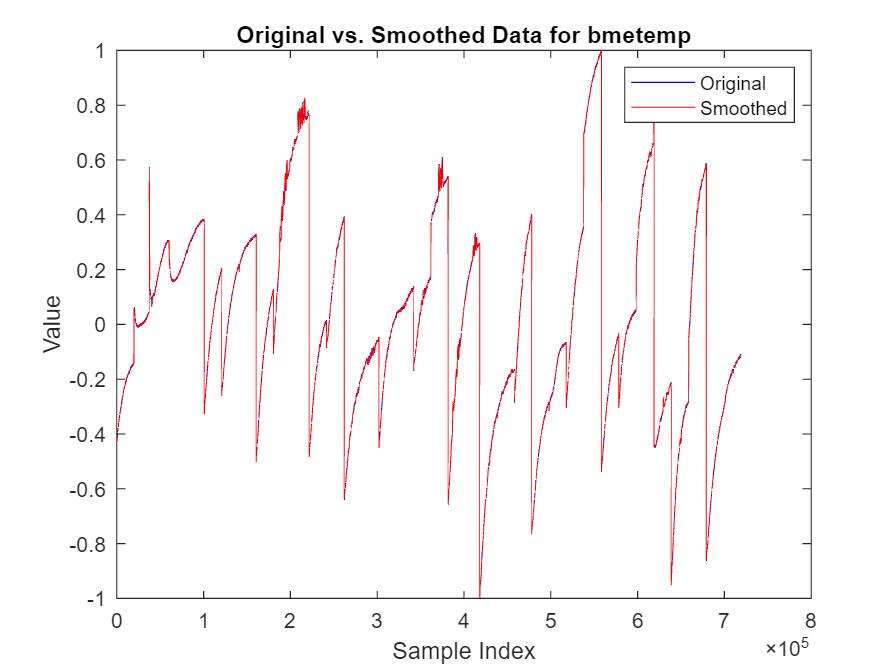

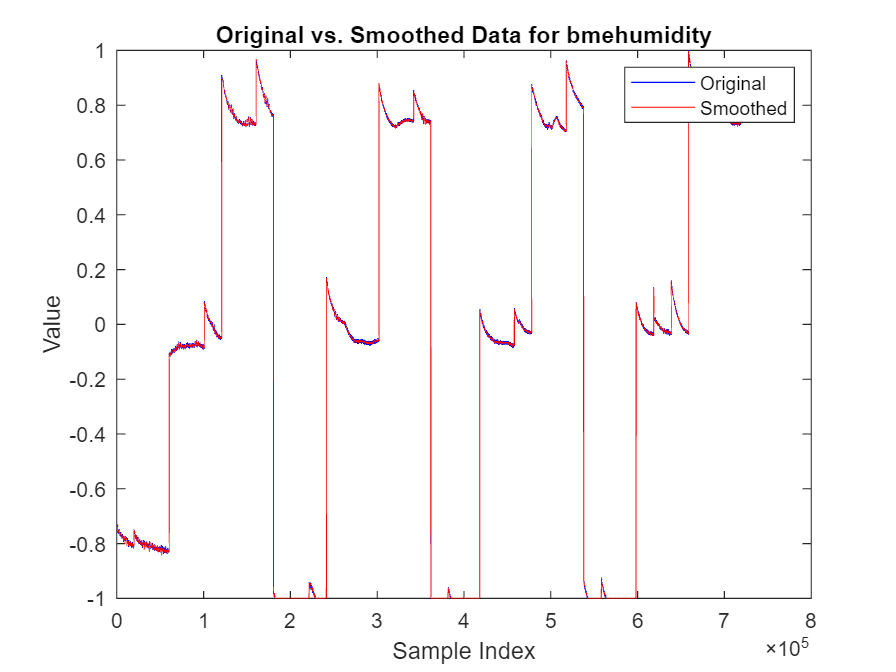

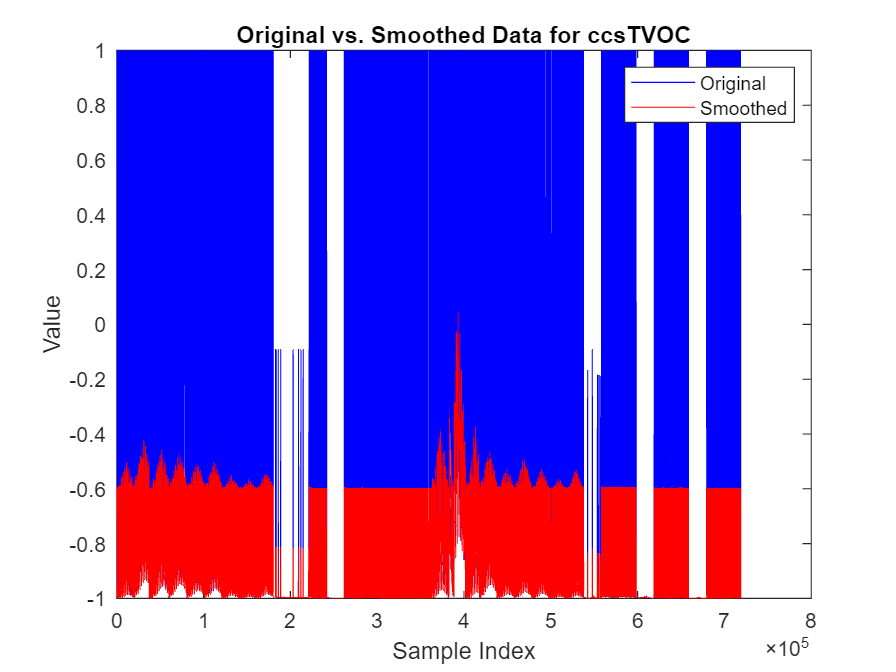

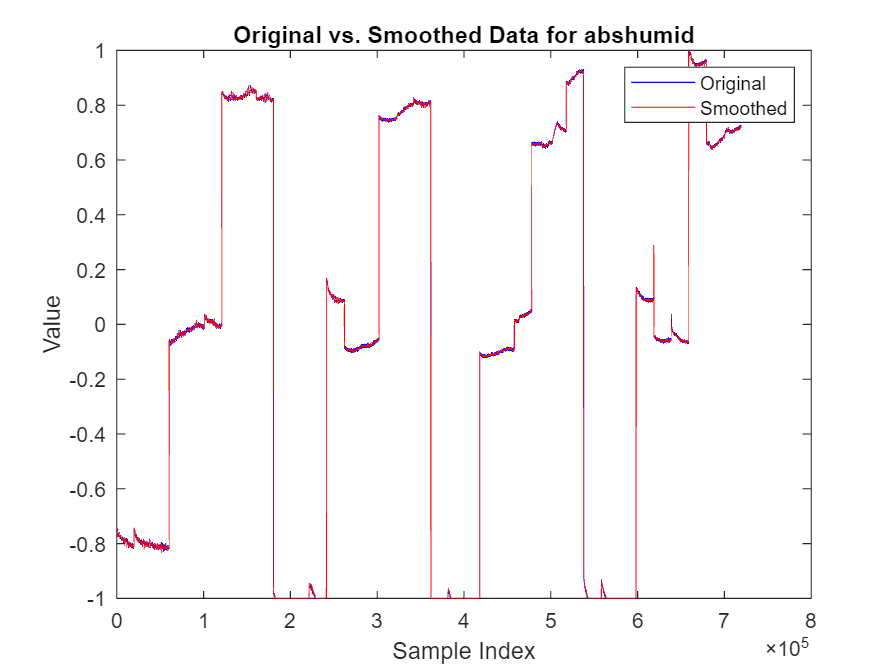

% Load or create your table (masterUrine)
% Assuming masterDatacopy is already loaded or created

% Define the window size for the moving average filter
windowSize = 5; % You can adjust this based on your requirements

% Extract data from the 3rd column to the last, skipping the first two
dataToSmooth = masterDatacopy{:, 3:end};

% Initialize a table for the smoothed data, including the first two columns
smoothedData = masterDatacopy(:, 1:2); % Initialize with the first two columns

% Apply a moving average filter to each column starting from the 3rd using movmean
for col = 1:size(dataToSmooth, 2) % Adjust loop to start from the 3rd column
    colIndex = col + 2; % Adjusted index for extracting column names
    colName = masterDatacopy.Properties.VariableNames{colIndex}; 
    % Apply centered moving average using movmean
    smoothedColumn = movmean(dataToSmooth(:, col), windowSize, 'Endpoints', 'discard');
    % Since 'Endpoints', 'discard' might reduce the size, pad the beginning
    % and end to match the original data size (optional, based on requirement)
    padSize = (windowSize - 1) / 2;
    paddedSmoothedColumn = padarray(smoothedColumn, [padSize, 0], 'replicate', 'both');
    % Adjust the length if necessary (e.g., for even window sizes)
    paddedSmoothedColumn = paddedSmoothedColumn(1:size(dataToSmooth, 1), :);
    % Add the smoothed column to the table
    smoothedData = addvars(smoothedData, paddedSmoothedColumn, 'NewVariableNames', {colName});
    
    % Plotting the original vs. smoothed data
    figure; % Create a new figure for each column
    plot(1:size(dataToSmooth, 1), dataToSmooth(:, col), 'b', 'DisplayName', 'Original'); hold on; % Original data in blue
    plot(1:size(dataToSmooth, 1), paddedSmoothedColumn, 'r', 'DisplayName', 'Smoothed'); % Smoothed data in red
    title(['Original vs. Smoothed Data for ', colName]);
    xlabel('Sample Index'); % Using a generic x-axis label since we're not plotting the first two columns
    ylabel('Value');
    legend('show');
end


% Display the original and smoothed data for comparison
disp(masterDatacopy)

    Chem_Comp      mox1        mox2        mox3       moxtemp        mics         bmetemp      bmehumidity     ccsTVOC      abshumid       sgpTVOC      sgpRawEthanol     sgpRawH2  
    _________    ________    ________    ________    __________    _________    ___________    ___________    _________    ___________    __________    _____________    ___________

        1        -0.99821    -0.99955    -0.99506      -0.14116     -0.51611       -0.42857       -0.72758     -0.99988       -0.74379            -1         0.57843         0.55768
        1     